# Welcome to the Macquarie MEG Tutorial! 

This tutorial will guide you through the basic preprocessing steps of MEG analysis, for data acquired from the KIT-Macquarie Research Laboratory.   

## Experimental Paradigm

A static simple visual grating (2 cycles per degree) is presented to participants for 1.5s. There is 2s baseline before each presentation of the visual grating

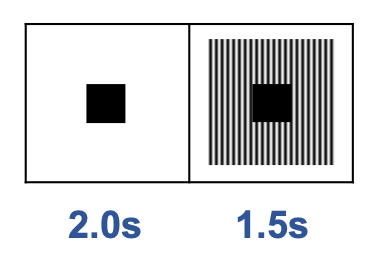

## Set-up Paths

The first step will be set up the paths on your machine. 

You will need to following toolboxes, which can be downloaded from Github 

- [Fieldtrip Toolbox](http://www.fieldtriptoolbox.org/)

- [MQ_MEG_Scripts](https://github.com/Macquarie-MEG-Research/MQ_MEG_Scripts)

You will also need to download the sample MEG data. This can be accessed via:

- [TO BE UPDATED]

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 1. Set up paths
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Path to the raw data (make sure this ends with /)
data_path               = '/Volumes/Robert T5/sample_data/';

% Path to where the data should be saved (make sure this ends with /)
save_path               = '/Volumes/Robert T5/sample_data_processed/';

% Path to the Fieldtrip Toolbox
path_to_fieldtrip       = '/Users/rseymoue/Documents/GitHub/fieldtrip';
 
% Path to MQ_MEG_Scripts
path_to_MQ_MEG_Scripts  = '/Users/rseymoue/Documents/GitHub/MQ_MEG_Scripts/';


## Add Toolboxes to MATLAB path

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 2. Add Fieldtrip and MQ_MEG_Scripts to path
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

addpath(path_to_fieldtrip);
ft_defaults

warning(['Please note that MQ_MEG_Scripts is designed for'...
    ' MATLAB 2016b or later and have been tested using Fieldtrip'...
    ' version 20181213']);
addpath(genpath(path_to_MQ_MEG_Scripts));


## Specify Subject ID 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 3. Specifiy Subject ID
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subject = '3566';


## Create Folder for Saving

I prefer to separate the 'raw' data folder from the 'processed' data folder, mainly so I don't accidently erase the raw data, but also so I don't end up with a large folder with mixture of disorganised results

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 4. Make a subject specific results folder for saving
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Get the path to the saving directory
dir_name = [save_path subject];
% Make the directory!
mkdir(dir_name);


## Specify File-paths

We now need to specify the path to the `.con, .mrk, .elp and .hsp` files

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 5. Specify paths to confile, mrkfile, elpfile and hspfile
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

confile = [data_path 'sub-' subject '/ses-1/meg/sub-' subject...
    '_ses-1_task-alien_run-1_meg.con'];

mrkfile = [data_path 'sub-' subject...
    '/ses-1/meg/sub-' subject '_ses-1_task-alien_run-1_markers.mrk'];

% Find files ending in .elp (if you have more than one .elp file you will need
% to modify this code)
elpfile = dir([data_path 'sub-' subject...
    '/ses-1/extras/*.elp']);
elpfile = [elpfile.folder '/' elpfile.name];

% Find files ending in .hsp (if you have more than one .hsp file you will need
% to modify this code)
hspfile = dir([data_path 'sub-' subject...
    '/ses-1/extras/*.hsp']);
hspfile = [hspfile.folder '/' hspfile.name];

% Get the path to the saving directory
dir_name = [save_path subject];
cd(dir_name);


## Saturations

Sometimes the data contains saturations (periods when MEG channel(s) flat-lines due to low-frequency nose). The `mq_detect_satuations` function can be used to detect the channels and times with saturations

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 6. Check for saturations
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

[sat] = mq_detect_saturations(dir_name,confile)
save sat sat


Here we see that MEG channels 1 and 2 saturate for around 2s during the recording:

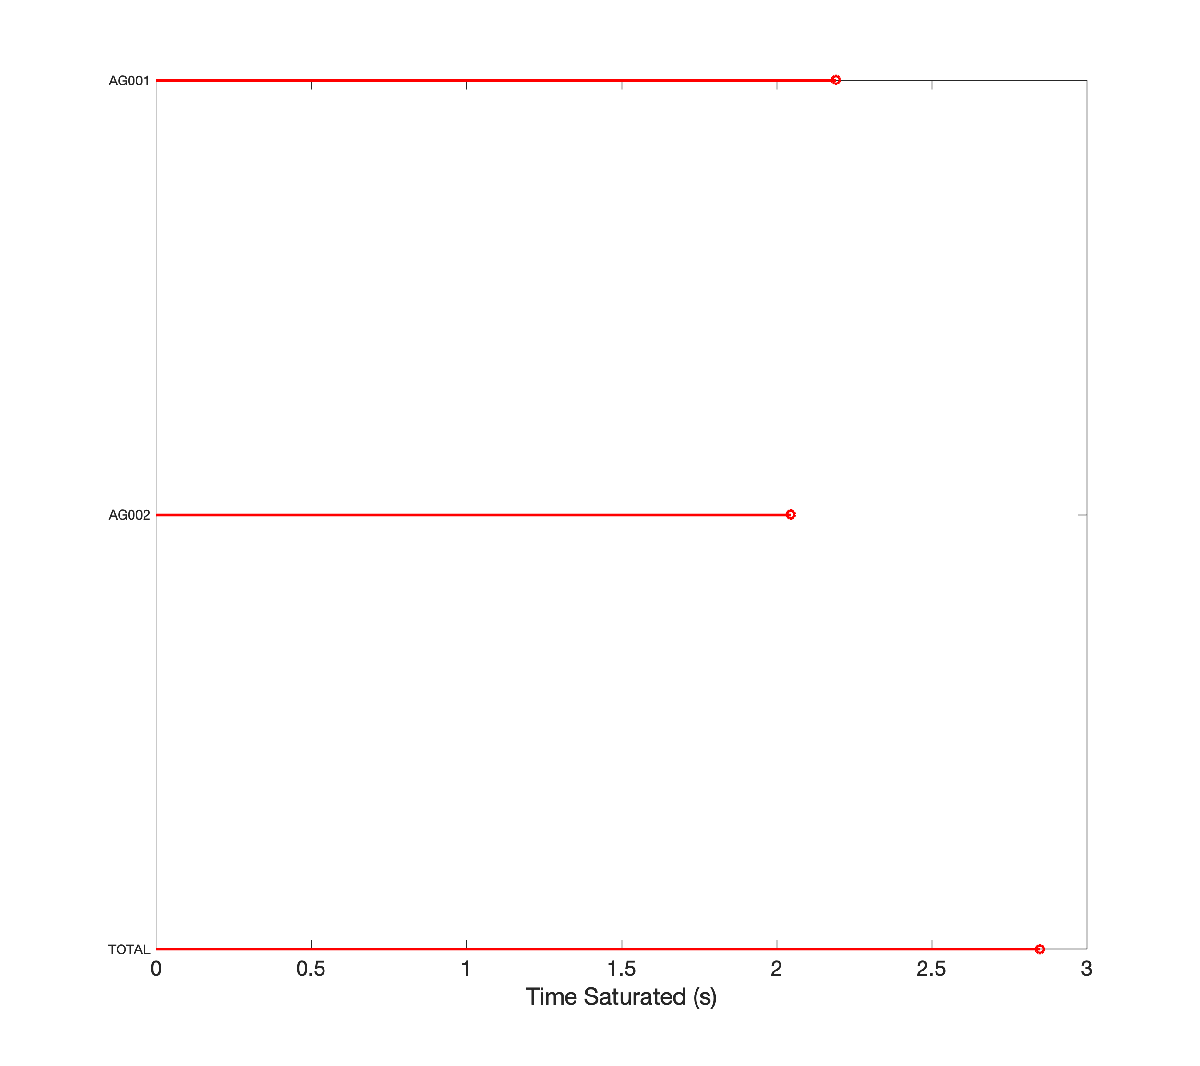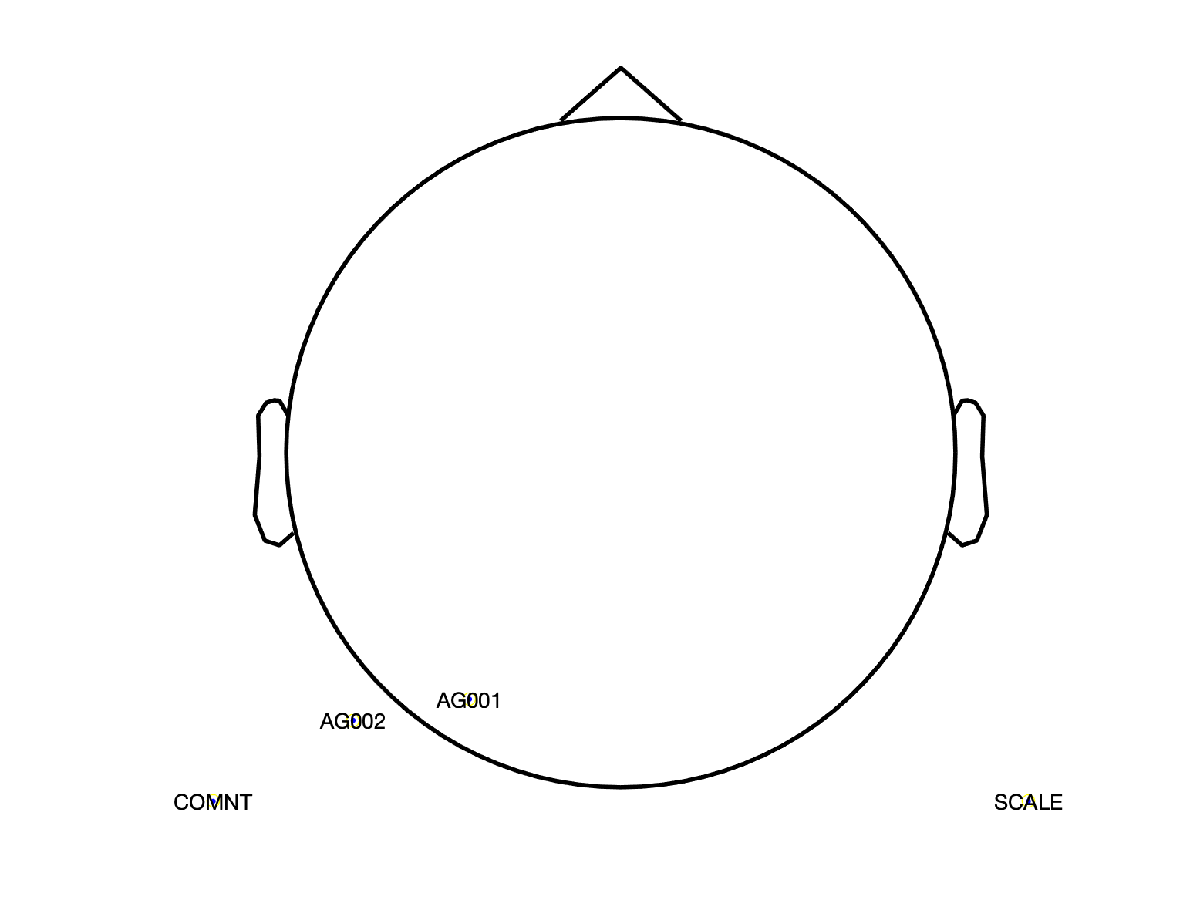

## Downsample Headshape

For accurate co-registration later we need to downsample the headshape information acquired before the scan, using the `downsample_headshape `function. If you are not intending to perform source analysis, you can ignore this step.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 7. Downsample Headshape
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

headshape_downsampled = downsample_headshape(hspfile,'yes',2);
figure; ft_plot_headshape(headshape_downsampled);

% Save
cd(dir_name);
disp('Saving headshape_downsampled');
save headshape_downsampled headshape_downsampled;


Here we see how the function downsampled the headshape, whilst keeping some useful facial information:

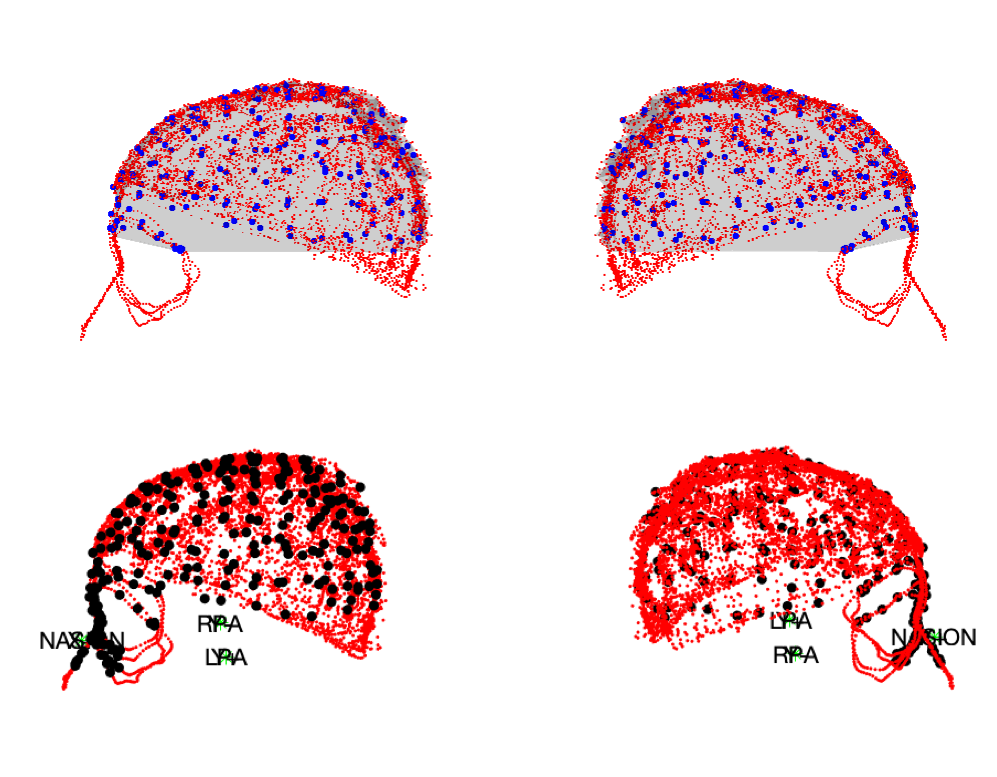

## **Realign Sensors**

For accurate source analysis, we need the marker coils, anatomical landmarks and headshape information to be represented in the same co-ordinates as the MEG sensors. One could transform the marker coils, anatomical landmarks and headshape information into the native MEG co-ordinate system. However, we will opt to transform the other way around: transforming the MEG sensors into the BTI co-ordinate system. Again, if you are not intending to perform source analysis, you can ignore this step.

In practice, this is achieved by transforming between the locations specified by the 5 coils in the .mrk (MEG co-ordinate system) and the locations of the 5 coils in the .elp file, digititised as part of head digitisation procedure. The `mq_realign_sens` function performs this procedure for you:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 8. Realign Sensors
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

[grad_trans] = mq_realign_sens(dir_name,elpfile,hspfile,...
    confile,mrkfile,'','rot3dfit');

print('grad_trans','-dpng','-r200');


Here, we see how the marker coils, anatomical landmarks and headshape information are represented in the same co-ordinates as the MEG sensors:

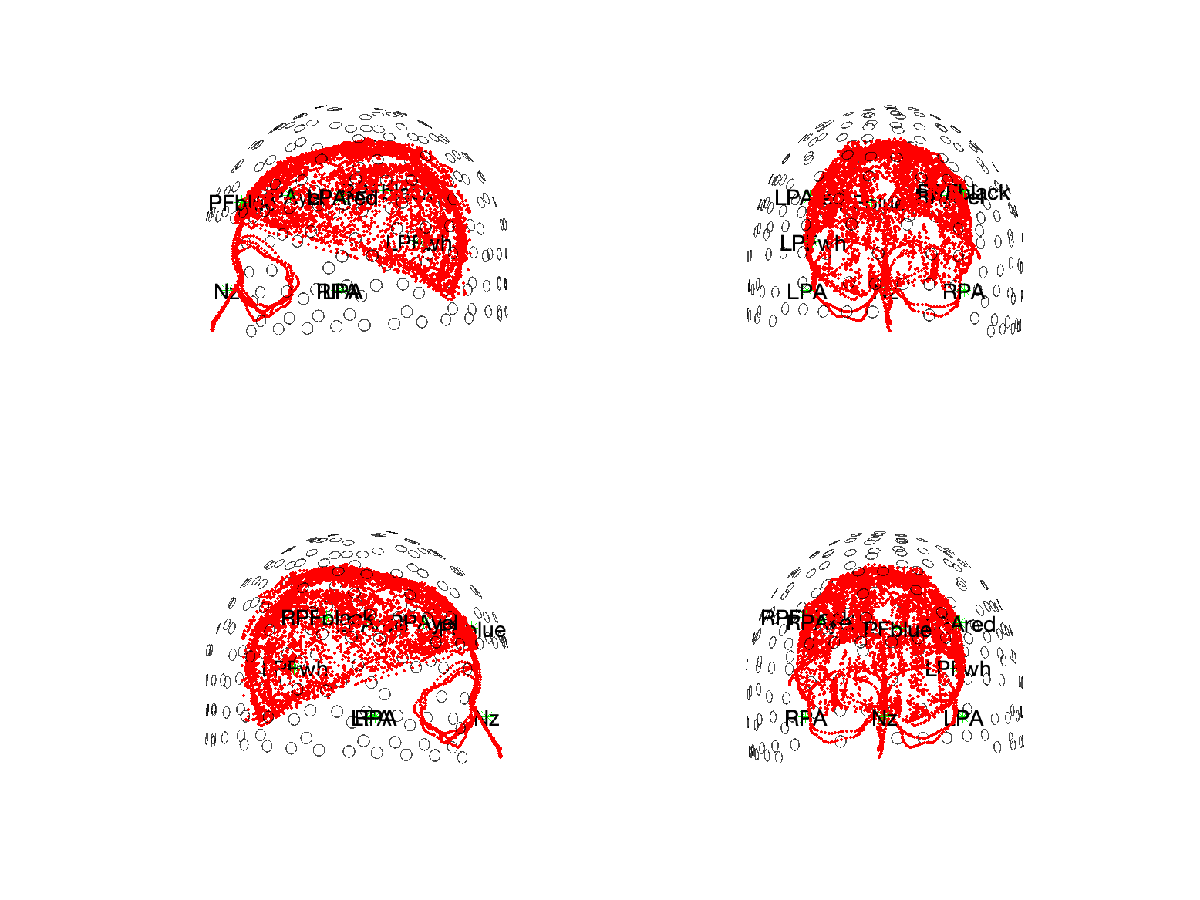

**Bad Coils:**

If you have a bad coil(s) you can enter these as the 6th argument to the function:  `{'LPAred','RPAyel','PFblue','LPFwh','RPFblack'} `

For example to exclude the red coil...

[grad_trans] = mq_realign_sens(dir_name,elpfile,hspfile,...
    confile,mrkfile,{'LPAred'},'icp');

*NOTE 1: You need at least three good coils for accurate realignment*

*NOTE 2: When excluding one or more coils, the 'icp' method is preffered to the 'rot3dfit' method*

## Read in MEG Data

The first step in analysing the MEG data in the `.con` file will be to load the data into MATLAB using the Fieldtrip toolbox.

After this, I tend to apply a band-pass filter of 0.5-250Hz, to improve the initial visualisation of the data.

**NOTE: Applying filters to your data should be done with caution. For example high-pass filtering above 1Hz results in dramatic effects on ERF shapes. **See these papers for more details: [[1] ](https://www.frontiersin.org/articles/10.3389/fpsyg.2011.00365/full#h6)[[2]](https://www.frontiersin.org/articles/10.3389/fpsyg.2012.00131/full) [[3]](https://doi.org/10.1016/j.jneumeth.2016.01.002).

As we will be analysing gamma-band activity with this data, we need to deal with 50Hz line noise and it's harmonics. Here opt for the easiest/bluntest approach with a band-stop filter around the . Fieldtrip does contain [fancier methods](http://www.fieldtriptoolbox.org/reference/ft_preproc_dftfilter/) if you are interested in this.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 9. Read in raw MEG data & apply filters
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% CD to correct directory
cd(dir_name);

% Epoch the whole dataset into one continous dataset and apply
% the appropriate filters
cfg             = [];
cfg.headerfile  = confile;
cfg.datafile    = confile;
cfg.trialdef.triallength = Inf;
cfg.trialdef.ntrials = 1;
cfg             = ft_definetrial(cfg)

cfg.continuous  = 'yes';
alldata         = ft_preprocessing(cfg);

% Band-pass filter between 0.5-250Hz to help visualisation
cfg.continuous  = 'yes';
cfg.bpfilter    = 'yes';
cfg.bpfreq      = [0.5 250];
alldata         = ft_preprocessing(cfg);

% Deal with 50Hz line noise using a bandstop filter
cfg             = [];
cfg.bsfilter    = 'yes';
cfg.bsfreq      = [49.5 50.5];
alldata         = ft_preprocessing(cfg,alldata);

% Deal with 100Hz line noise using a bandstop filter
cfg             = [];
cfg.bsfilter    = 'yes';
cfg.bsfreq      = [99.5 100.5];
alldata         = ft_preprocessing(cfg,alldata);

% Create layout file for later and save
cfg             = [];
cfg.grad        = alldata.grad;
lay             = ft_prepare_layout(cfg, alldata);
save lay lay

% Cut out MEG channels
cfg         = [];
cfg.channel = alldata.label(1:160);
alldata     = ft_selectdata(cfg,alldata);


## Epoching

We now need to epoch the data into trials, based on the onset of the visual grating stimulus. This is specified by a trigger, coded in MEG channel 181.

Please see separate 'Creating a Trial Definition Function' for more details

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 10. Epoch the data into trials
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

cfg = [];
cfg.dataset                 = confile;
cfg.continuous              = 'yes';
cfg.trialdef.prestim        = 2.0;         % pre-stimulus interval
cfg.trialdef.poststim       = 2.0;        % post-stimulus interval
cfg.trialfun                = 'mytrialfun_new_alien';
data_raw                    = ft_definetrial(cfg);

% Redefines the filtered data
cfg                         = [];
data                        = ft_redefinetrial(data_raw,alldata);


## Visual Bad Trial Removal

A crucial part of pre-processing is the removal of trials contaminated by artefacts. These include artefacts caused by subject movement, cardiac actiivity, eye movements, jaw clenching etc.. Whilst some MEG groups are working on automatic pipelines for artefact rejection (e.g. [Jas et al., 2017](https://doi.org/10.1016/j.neuroimage.2017.06.030)), often the most time-efficient way is to visually inspect your data. 

In this example, when plotting the data we have removed 3 "bad" channels containing a lot of artfactual noise (channels 1,2,68).

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 11. Visually Inspect data for "bad" trials
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

cfg                 = [];
cfg.channel         = {'MEG','-AG001','-AG002','-AG068'};
cfg.colorgroups     = 'allblack';
cfg.viewmode        = 'vertical';
cfg.plotevents      = 'no'; 
ft_databrowser(cfg,data)

% Load the summary again so you can manually remove any bad trials
cfg             = [];
cfg.method      = 'summary';
cfg.keepchannel = 'yes';
grating         = ft_rejectvisual(cfg, data);

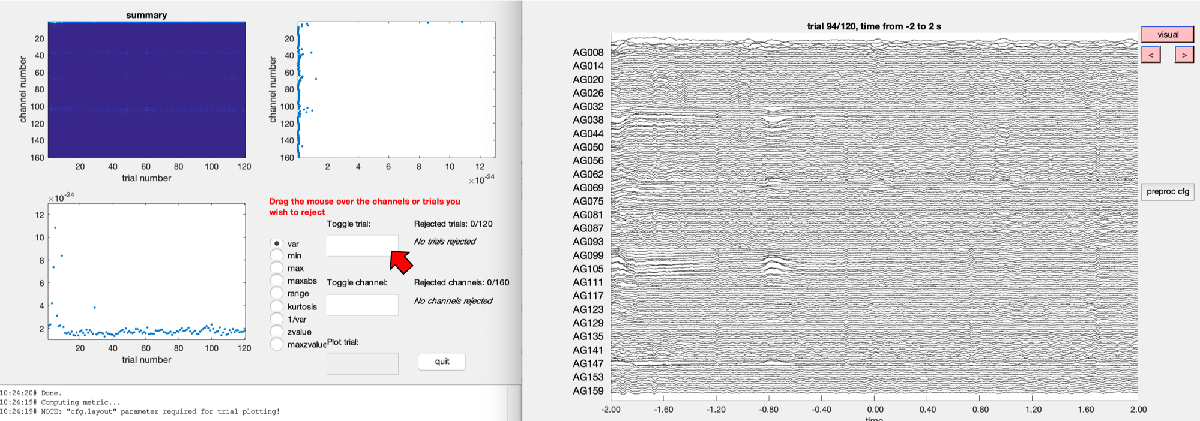

In trial 9, there is a clear muscle artefact around -1.6s pre-stimulus onset:

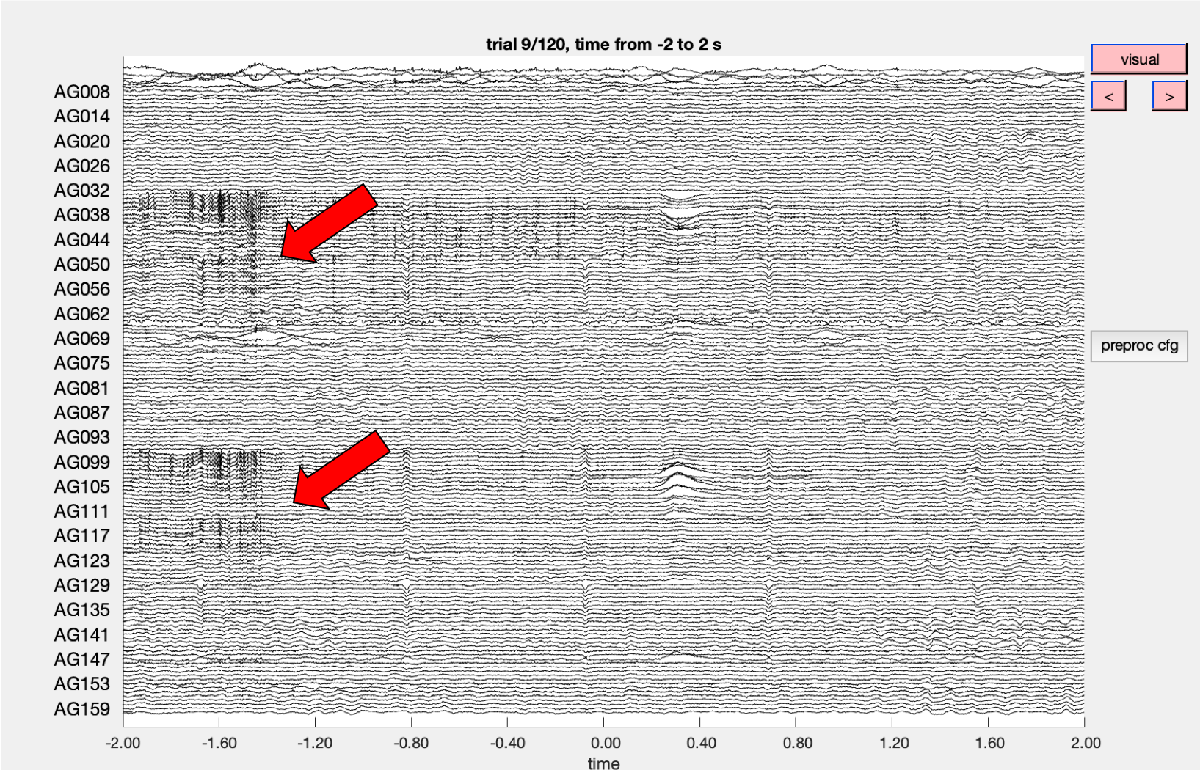

*NOTE 1: Enter the bad trials in the box highlighted with the red arrow*

*NOTE 2: Take extra time to examine trials with high variance values*

*NOTE 3: If you enter a trial incorrectly, simply quit and re-run this code*

## Perform Independent Component Analysis (ICA)

A robust method to reduce artefacts arising from cardiac activity and eye movements is ICA.

For more details on ICA, please see:

- [Fieldtrip EOG Tutorial](http://www.fieldtriptoolbox.org/example/use_independent_component_analysis_ica_to_remove_eog_artifacts/)

- [Wikipedia Page](https://en.wikipedia.org/wiki/Independent_component_analysis)

- [ICA for dummies](http://arnauddelorme.com/ica_for_dummies/)

- [SCCN ICA Tutorial](https://sccn.ucsd.edu/wiki/Chapter_09:_Decomposing_Data_Using_ICA)

Here we opt to use the '[fastica](https://www.cs.helsinki.fi/u/ahyvarin/papers/fastica.shtml)' algorithm, which is a robust but computationally efficient way to perform ICA

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 12. Perform ICA & Remove ECG/EOG artefacts
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Downsample Data
grating_orig    = grating; %save the original CLEAN data for later use 
cfg             = []; 
cfg.resamplefs  = 150; %downsample frequency 
cfg.detrend     = 'no'; 
disp('Downsampling data');
grating            = ft_resampledata(cfg, grating_orig);

% Run ICA
disp('About to run ICA using the Runica method')
cfg                 = [];
cfg.method          = 'fastica';
cfg.numcomponent    = 50;
cfg.feedback        = 'textbar';
comp                = ft_componentanalysis(cfg, grating);

% Display Components - change layout as needed
cfg             = []; 
cfg.compscale   = 'local';
cfg.viewmode    = 'component'; 
cfg.layout      = lay;
cfg.position    = [1 1 800 700];
cfg.ylim        = [ -2.8015e-11  5.7606e-11 ];
cfg.blocksize   = 4;
ft_databrowser(cfg, comp);

ft_hastoolbox('brewermap',1);
colormap123     = colormap(flipud(brewermap(64,'RdBu')));

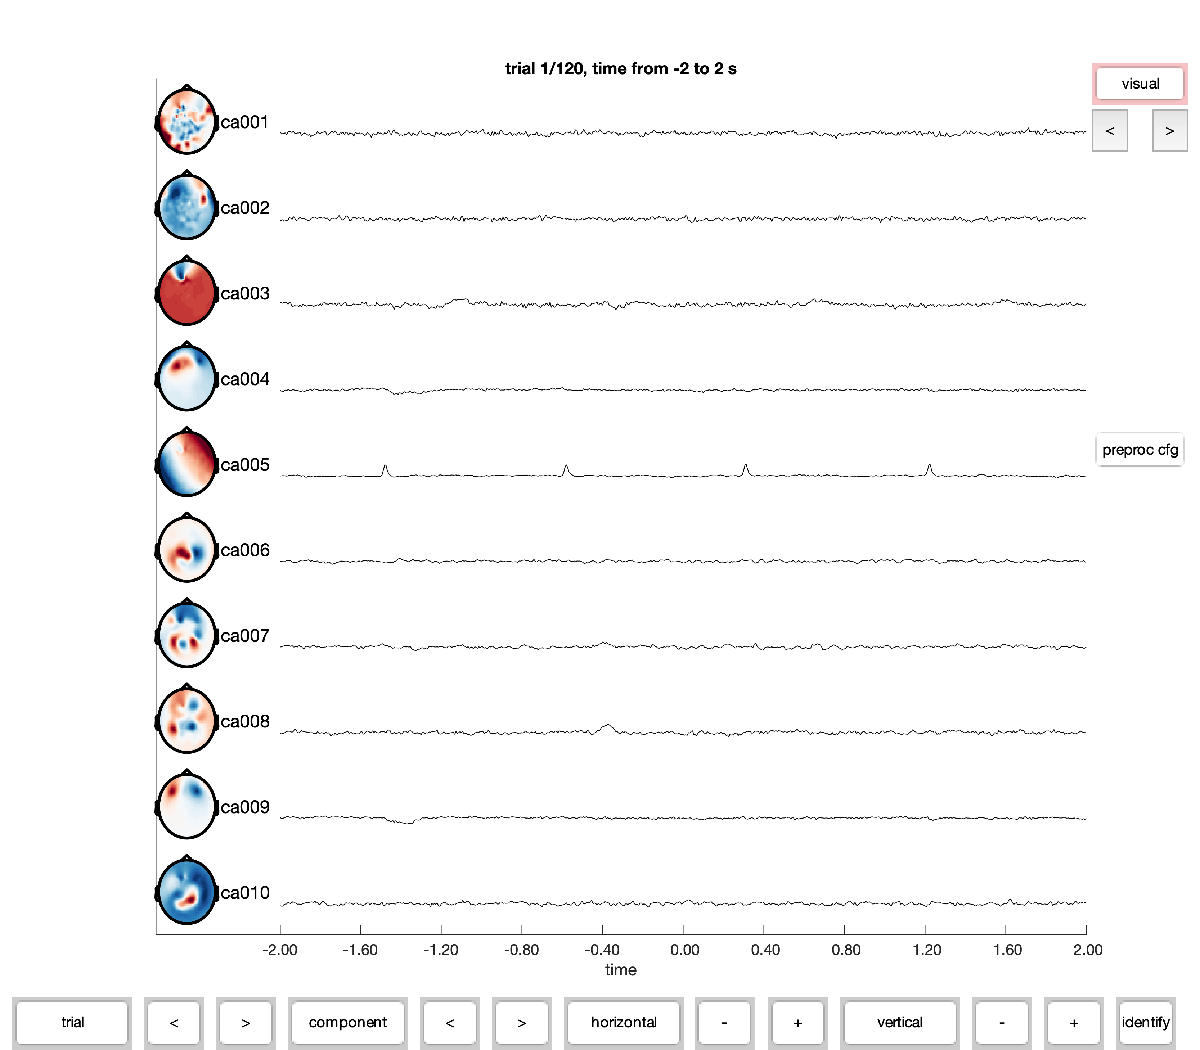

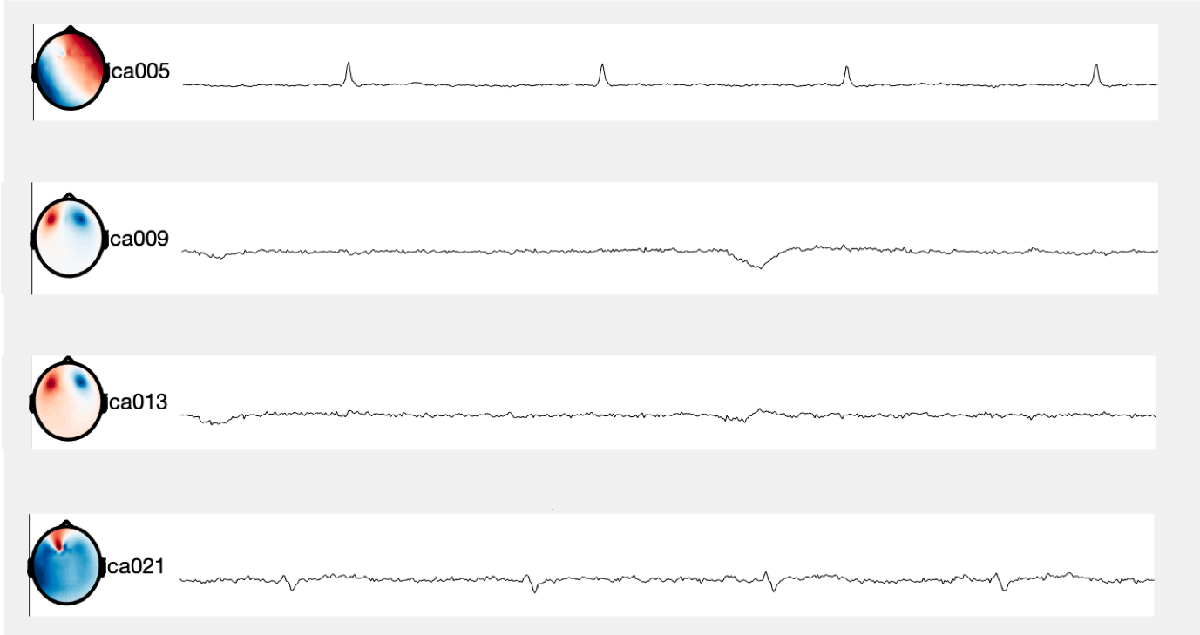

Here I have plotted 4 components (from different trials) with clear artefactial sources. Components 5 & 21 contain cardiac artefacts, whereas componenets 9 & 13 contain ocular (eye movement) artefacts. 

To remove these from your data use the code below. The MATLAB command window can be used to enter the components  to be removed in the form: [5 9 13  21]

% Decompose the original data as it was prior to downsampling 
disp('Decomposing the original data as it was prior to downsampling...');
cfg           = [];
cfg.unmixing  = comp.unmixing;
cfg.topolabel = comp.topolabel;
comp_orig     = ft_componentanalysis(cfg, grating_orig);

%% The original data can now be reconstructed, excluding specified components
% This asks the user to specify the components to be removed
disp('Enter components in the form [1 2 3]')
comp2remove     = input('Which components would you like to remove?\n');
cfg             = [];
cfg.component   = [comp2remove]; %these are the components to be removed
data_clean      = ft_rejectcomponent(cfg, comp_orig,grating_orig);

## Plot the Clean Data

cfg = [];
cfg.channel         = {'MEG','-AG001','-AG002','-AG068'};
cfg.colorgroups     = 'allblack';
cfg.viewmode        = 'vertical';
cfg.plotevents      = 'no'; 
ft_databrowser(cfg,data_clean);